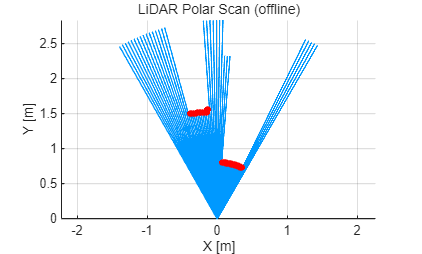

%% lidar_plot_offline.m  ---------------------------------------------
% 저장한 한 프레임(csv) 불러와서 폴라 스캔 재현

% ---------- 1. 파일 읽기 ----------
fileName = 'resource/data/lidar/lidar_000033.csv';   % ← 경로/이름 수정
rangeMat = readmatrix(fileName);

% ---------- 2. 센서 파라미터 (Webots 설정과 동일해야 함) ----------
hRes = size(rangeMat,2);          % 수평 해상도
nLayer = size(rangeMat,1);        % 수직 레이어 수
fov   = deg2rad(60);              % 수평 FoV [rad]  ← 예: 60°
maxR  = 8.0;                      % 최대 거리 [m]   ← world 파일과 일치

% ---------- 3. 가운데 레이어 하나 선택 ----------
rValues  = rangeMat( ceil(nLayer/2), : );

% ---------- 4. 극 → 직교 변환 ----------
thetaVec = linspace( fov/2 , -fov/2 , hRes );  % +왼 → −오른
xEnd = -rValues .* sin(thetaVec);
yEnd =  rValues .* cos(thetaVec);

% ---------- 5. 유효 히트 필터 (빈 빔 제거) ----------
tol   = 6;%0.05;                               % 5 cm 여유
isHit = (rValues < maxR - tol) & ~isinf(rValues) & ~isnan(rValues);

% ---------- 6. 그림 ----------
figure('Name','Offline LiDAR Polar Scan','NumberTitle','off');
ax = axes; hold(ax,'on'); axis(ax,'equal'); grid(ax,'on');
xlabel('X [m]'); ylabel('Y [m]'); title('LiDAR Polar Scan (offline)');

% (a) 모든 빔 파란 선
for k = 1:hRes
    line(ax,[0 xEnd(k)],[0 yEnd(k)],'Color',[0 0.6 1 0.5]);  % 0.5=알파
end

% (b) 히트 점 빨간 scatter
scatter(ax,xEnd(isHit),yEnd(isHit),25,'filled','r');

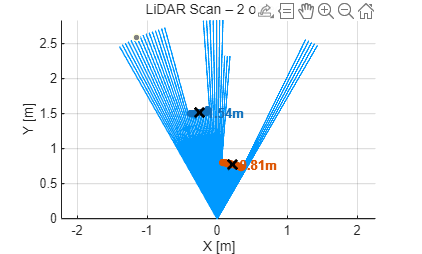


%% -------- 7. DBSCAN 군집화 · 객체별 거리 계산 -----------------
% ▶ 7-1) (x,y) 히트 좌표 배열
xyHits = [xEnd(isHit).' , yEnd(isHit).'];      % [N×2]

% ▶ 7-2) DBSCAN 실행  (eps·minPts는 장면 규모에 따라 조정)
eps    = 0.15;    % 한 클러스터 내 최대 점-간 거리 [m]
minPts = 4;       % 최소 점 개수(노이즈 제거용)
clabel = dbscan(xyHits, eps, minPts);          % 벡터 길이 = N

% ▶ 7-3) 노이즈(라벨 −1) 제거
valid  = clabel > 0;
xyC    = xyHits(valid,:);    cID = clabel(valid);

% ▶ 7-4) 클러스터별 특성치
uID  = unique(cID);                  % 실제 객체ID 목록
nObj = numel(uID);                   % 검출된 물체 개수
objCentroid = zeros(nObj,2);         % (x,y) 중심
objDist     = zeros(nObj,1);         % 원점(로봇)까지 거리

for i = 1:nObj
    idx = (cID == uID(i));
    objCentroid(i,:) = mean(xyC(idx,:),1);         % 산술평균
    objDist(i)       = hypot(objCentroid(i,1), ...
                             objCentroid(i,2));    % √(x²+y²)
end

% ▶ 7-5) 시각화 : 각 클러스터 다른 색 + 중심 '×'
cmap = lines(max(uID));     % 색상 팔레트
for i = 1:nObj
    idx = (cID == uID(i));
    scatter(ax, xyC(idx,1), xyC(idx,2), 30, ...
            'filled', 'MarkerFaceColor', cmap(uID(i),:));
    plot(ax, objCentroid(i,1), objCentroid(i,2), ...
         'kx', 'MarkerSize',10,'LineWidth',2);
    text(objCentroid(i,1), objCentroid(i,2), ...
        sprintf('  %.2fm',objDist(i)) , ...
        'Color',cmap(uID(i),:),'FontWeight','bold');
end
title(ax, sprintf('LiDAR Scan – %d objects', nObj));


fprintf('Detected %d objects\n', nObj);

Detected 2 objects


disp(table((1:nObj).', objCentroid, objDist, ...
     'VariableNames',{'ID','Centroid_xy','Range_m'}));

    ID        Centroid_xy         Range_m
    __    ____________________    _______

    1     -0.25918      1.5174     1.5393
    2       0.2134     0.77661    0.80539



## --------------------------------------------------------------

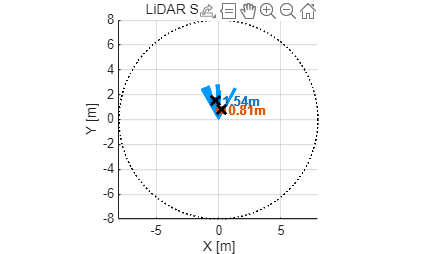


% (c) 외곽 원
t = linspace(0,2*pi,360);
plot(ax,maxR*cos(t),maxR*sin(t),'k:');
xlim(ax,[-maxR maxR]); ylim(ax,[-maxR maxR]);